clear;clc
load xi_1_mean_ave10
load xi_1_lower_ave10
load xi_1_upper_ave10

% load('Sx\omega_VaryingEndpoint.mat')
% load('Sx\lambda_VaryingEndpoint.mat')

load('Sz\omega.mat')
load('Sz\lambda.mat')
load('Sz\omega_upper_bound.mat')
load('Sz\lambda_upper_bound.mat')
load('Sz\omega_lower_bound.mat')
load('Sz\lambda_lower_bound.mat')
load('Sz\cc.mat')
load('Sz\dd.mat')
load('Sz\S.mat')
load('Sz\S_uncert.mat')

load('J1.mat')
load('J1_uncert.mat')



J1_seq=reshape(J1_seq,[70,1]);
mean(J1_seq)

ans = 1.4595e+03

max(J1_seq)

ans = 1.4992e+03

min(J1_seq)/max(J1_seq)

ans = 0.9571


J_bar=mean(J1_seq)*1e-3; %in kHz
mean_omega=mean(omega)/J_bar

mean_omega =     0.5907    0.4307    0.2523    0.0712    0.0066    0.0064         0    0.0004    0.0038    0.0345    0.2635    0.4527    0.6125


mean_lambda=mean(lambda)/J_bar

mean_lambda =     0.5633    0.4894    0.3762    0.2245    0.0913    0.0303    0.0013    0.0247    0.0890    0.2030    0.3911    0.5048    0.5548




upperbar_omega=(max(omega_upper_bound)-mean(omega))/J_bar;
upperbar_lambda=(max(lambda_upper_bound)-mean(lambda))/J_bar;
lowerbar_omega=(-min(omega_lower_bound)+mean(omega))/J_bar;
lowerbar_lambda=(-min(lambda_lower_bound)+mean(lambda))/J_bar;


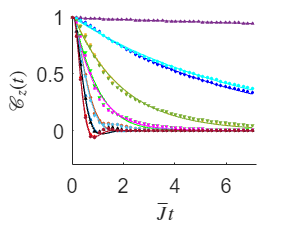

figure()
color={    "#FF0000"
    "#0072BD"
    "#D95319"
    "#00FF00"
    "#EDB120"
    "#0000FF"
    "#7E2F8E"
    "#00FFFF"
    "#77AC30"
    "#FF00FF"
    "#4DBEEE"
    "#000000"
    "#A2142F"
    };
% color={
%  [0.742077, 0.0624857, 0.00605783]
%  [0, 0.501961, 0],
%  [0.891279, 0.721172, 0.777905],
%  [0.0620432, 0.521904, 0.704387],
%  [0.823529, 0.663981, 0.00828565],
%  [1, 0.0175937, 0.505959],
%  [0.162524, 0.167422, 0.153964],
%  [0.904982, 0.676844, 0.566705],
%  [0.475792, 0.675181, 0.189776],
%  [0.760174, 0.00823987, 0.412406],
%  [0, 0.390173, 0.773754],
%  [1, 0.904479, 0.279423]
%   [0.0184939, 0.438911, 0.147189]
% };
% color={
%  [0.471412, 0.108766, 0.527016],
%  [0.290949, 0.153515, 0.699363],
%  [0.246296, 0.315957, 0.80044],
%  [0.266122, 0.486664, 0.802529],
%  [0.324106, 0.60897, 0.708341],
%  [0.406721, 0.686486, 0.575445],
%  [0.513417, 0.72992, 0.440682],
%  [0.640113, 0.743342, 0.338781],
%  [0.764712, 0.728302, 0.273608],
%  [0.863512, 0.670771, 0.236564],
%  [0.901627, 0.539872, 0.208366],
%  [0.886356, 0.346793, 0.170992],
%  [0.857359, 0.131106, 0.132128]
% };
marker=flip({'.','^','d','s','v','.','^','d','s','v','.','^','d'});
markersize=flip([5,1,1,1,1,5,1,1,1,1,5,1,1])*1;
ii=1;
endpoint=41;
for i=[1:13]

    tau=5*1e-6;
    td1=41;
    quench_time_seq=24*tau*(0:td1-1)*1e3; %in ms

    x=quench_time_seq(1:endpoint);
    y=S(i,1:endpoint)';

    errorbar(x*J_bar,y,FID_uncertainty(i,1:endpoint),marker{ii},'MarkerSize',markersize(ii),'MarkerFaceColor',color{ii},'Color',color{ii},'CapSize',1);
    hold on
    xx=0:1e-2:x(end);
    y_fit=cc(end,i)*cos(2*pi*omega(end,i)*xx+dd(end,i)).*exp(-2*pi*lambda(end,i)*xx);
    plot(xx*J_bar,y_fit,'color',color{ii})
    ii=ii+1;
end

xlabel('$\bar{J}t$','Interpreter','latex','FontSize',15)
ylabel('$\mathcal{C}_z(t)$','Interpreter',"latex",'FontSize',15)
ylim([-0.3 1])
yticks([-0.5 0 0.5 1])
yticklabels({'-0.5', '0', '0.5', '1'})
xlim([0 7.2])
xticks([0:2:6])
% xticklabels({'-0.5', '0', '0.5', '1'})

fontsize(gcf,10,'points')
fontname(gcf,"Helvetica")
set(gcf,'unit','centimeters','position',[10,10,5,4]);

set(gca,"box",'off')
saveas(gcf,'figures/c1.pdf')


xi_3=0.2;
xi_1=xi_1_mean';
xi_2=-xi_3-xi_1;
A=-6*xi_2.*xi_1;
B=xi_1.^2+xi_2.^2+xi_3.^2;
omega_theo=real(sqrt(A));
lambda_theo=sqrt(B)-(1-sign(A))/2.*sqrt(-A);

y=[mean_omega,mean_lambda]';
x=[omega_theo;lambda_theo];
[xData, yData] = prepareCurveData(x, y);

% 设置 fittype 和选项。
ft = fittype( 'c*x', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = 0.890903252535798;

% 对数据进行模型拟合。
[fitresult, gof] = fit( xData, yData, ft, opts )

fitresult =      常规模型:
     fitresult(x) = c*x
     系数(置信边界为 95%):
       c =      0.8649  (0.7655, 0.9642)

gof = 包含以下字段的 struct :
           sse: 0.2003
       rsquare: 0.8417
           dfe: 25
    adjrsquare: 0.8417
          rmse: 0.0895


conf=confint(fitresult)

conf =     0.7655
    0.9642


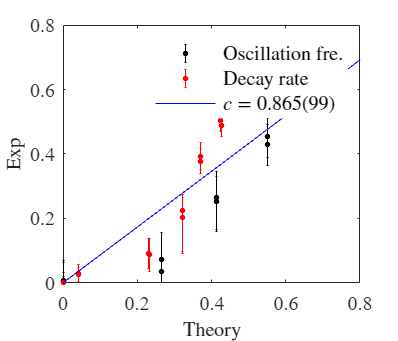

scale=fitresult.c;
scale_error=1/2*(conf(2)-conf(1));

% 绘制数据拟合图。
figure()
errorbar(omega_theo,mean_omega,lowerbar_omega,upperbar_omega,...
    '.','Markersize',8,'color','k','CapSize',1)
hold on
errorbar(lambda_theo,mean_lambda,lowerbar_lambda,upperbar_lambda,...
    '.','Markersize',8,'color','r','CapSize',1)
hold on
plot(0:1e-3:1,fitresult(0:1e-3:1),'-','Color','b')

xlim([0 0.8])
ylim([0 0.8])
xlabel('Theory','Interpreter','latex')
ylabel('Exp','Interpreter','latex')

legend('Oscillation fre.','Decay rate',['$c=',num2str(round(scale,3)),'(',num2str(1e3*round(scale_error,3)),')$'],'interpreter','latex','box','off','fontsize',5)
fontsize(gcf,10,'points')
fontname(gcf,"Times New Roman")
set(gcf,'unit','centimeters','position',[10,10,7,6]);
set(gca,'XTickLabelRotation',0)

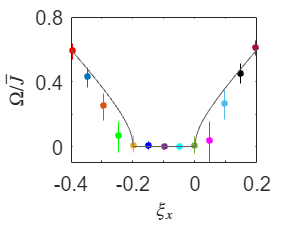

xi1_continuous=-0.4:1e-3:0.2;
xi_3=0.2;
xi_1=xi1_continuous';
xi_2=-xi_3-xi_1;
A=-6*xi_1.*xi_2;
B=xi_1.^2+xi_2.^2+xi_3.^2;

omega_fit=scale*real(sqrt(A));
lambda_fit=scale*sqrt(B)-(1-sign(A))/2.*sqrt(-A);

% omega_fit=c1*real(sqrt(A));
% lambda_fit=c2*sqrt(B)-c1*(1-sign(A))/2.*sqrt(-A);

x=xi_1_mean';
y=mean_omega;
figure()
for i=1:13
    errorbar(x(i),y(i),lowerbar_omega(i),upperbar_omega(i),xi_1_lower(i),xi_1_upper(i),...
        '.','Markersize',10,'color',color{i},'Markerfacecolor',color{i},'CapSize',0)
    hold on
end
plot(xi1_continuous,omega_fit,'-','Color',[96 96 96]/255)

xlim([-0.4 0.2])
xticks([-0.4:0.1:0.2])
xticklabels({'-0.4','','-0.2','','0','','0.2'})
ylim([-0.1 0.8])
yticks([0:0.2:0.8])
yticklabels({'0','','0.4','','0.8'})
xlabel('$\xi_x$','Interpreter','latex')
% ylabel('Fitted oscillation frequency $\omega/J$','Interpreter','latex')
ylabel('$\Omega/\bar{J}$','Interpreter','latex')

% title('The color gradient indicates varying $\xi_x$','Interpreter',"latex",'FontSize',16)
% legend('',['$c*\sqrt{A},\ c=',num2str(round(scale,3)),'(',num2str(1e3*round(scale_error,3)),')$'],'interpreter','latex','box','off','fontsize',5)
% legend('',['$c=',num2str(round(scale,3)),'(',num2str(1e3*round(scale_error,3)),')$'],'interpreter','latex','box','off','fontsize',5)

fontsize(gcf,10,'points')
fontname(gcf,"Helvetica")

set(gcf,'unit','centimeters','position',[10,10,5,4]);
set(gca,'XTickLabelRotation',0)
saveas(gcf,'figures/c2.pdf')

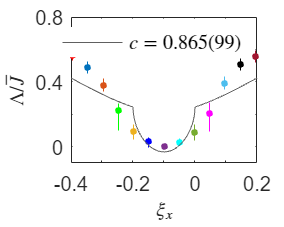

x=xi_1_mean';
y=mean_lambda;
figure()
for i=1:13
    errorbar(x(i),y(i),lowerbar_lambda(i),upperbar_lambda(i),xi_1_lower(i),xi_1_upper(i),...
        '.','Markersize',10,'color',color{i},'CapSize',0)
    hold on
end
plot(xi1_continuous,lambda_fit,'-','Color',[96 96 96]/255)
xlim([-0.4 0.2])
xticks([-0.4:0.1:0.2])
xticklabels({'-0.4','','-0.2','','0','','0.2'})
ylim([-0.1 0.8])
yticks([0:0.2:0.8])
yticklabels({'0','','0.4','','0.8'})
xlabel('$\xi_x$','Interpreter','latex')
% ylabel('Fitted oscillation frequency $\omega/J$','Interpreter','latex')
ylabel('$\Lambda/\bar{J}$','Interpreter','latex')

% title('The color gradient indicates varying $\xi_x$','Interpreter',"latex",'FontSize',16)
% legend('',['$c*\sqrt{A},\ c=',num2str(round(scale,3)),'(',num2str(1e3*round(scale_error,3)),')$'],'interpreter','latex','box','off')
legend('','','','','','','','','','','','','',['$c=',num2str(round(scale,3)),'(',num2str(1e3*round(scale_error,3)),')$'],'interpreter','latex','box','off')
% legend({'','','','','','','','','','','','',['$c_1=',num2str(round(c1,3)),'(',num2str(1e3*round(c1_error,3)),')$'], ['$c_2=',num2str(round(c2,3)),'(',num2str(1e3*round(c2_error,3)),')$']},'interpreter','latex','box','off')
fontsize(gcf,10,'points')
fontname(gcf,"Helvetica")

set(gcf,'unit','centimeters','position',[10,10,5,4]);
set(gca,'XTickLabelRotation',0)
saveas(gcf,'figures\c3.pdf')